# Sampling and Aliasing

## Sampling and Reconstruction at the Nyquist Frequency

Consider the analog signal $x_a(t) = \cos(20\,\pi\,t + \theta)$for $0 \le t \le 1$. It is sampled at $T_s = 0.05 $second intervals to obtain x[n]. Let $\theta = 0, \, \pi/6, \, \pi/4, \, \pi/2.$For each value of the $\theta$ values, perform the following.

- Plot $x_a(t)$ and superimpose x[n] on top of it using the plot(n,x,'o') function.

- Reconstruct the analog signal  from the samples x[n] using the sinc interpolation. Use $\Delta\,t = 0.001$, and superimpiose x[n] on it.

- You should observe that the resultant reconstruction in each case has the correct frequency but a different amplitude. Explain this observation. Comment on the role of the phase of $x_a(t)$on the sampling and reconstruction of signals.

Put your work here:

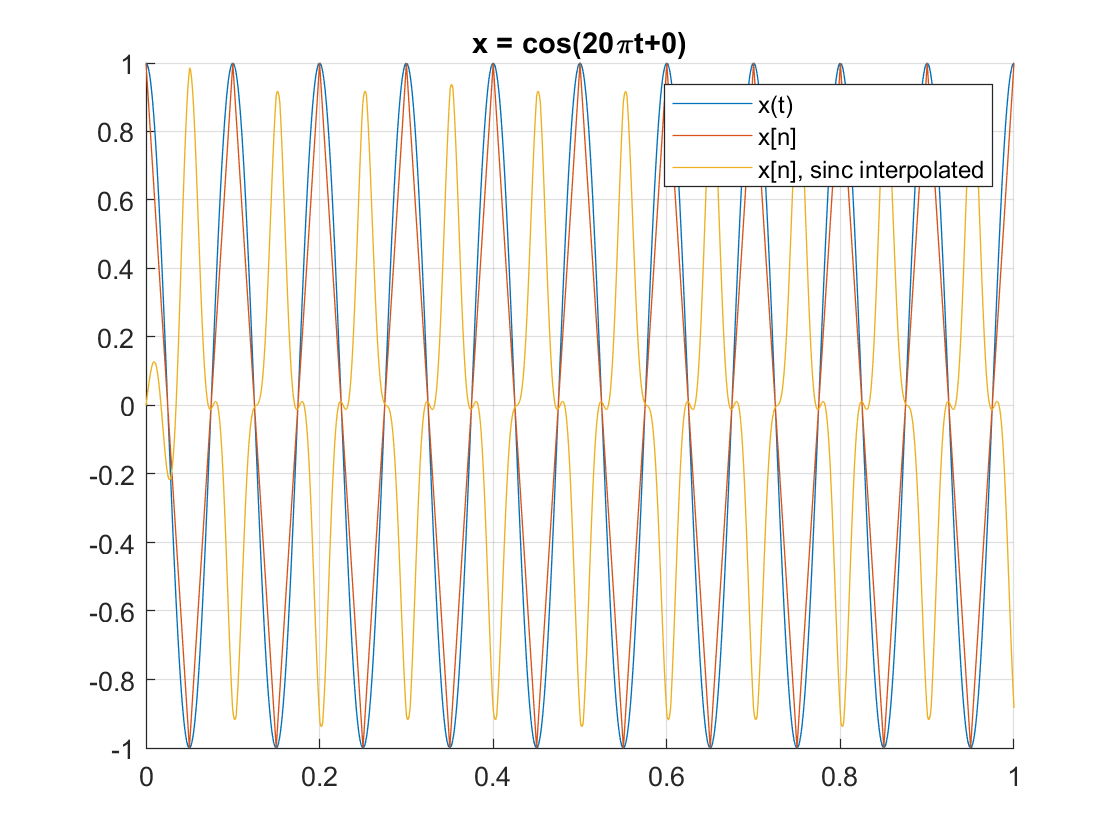

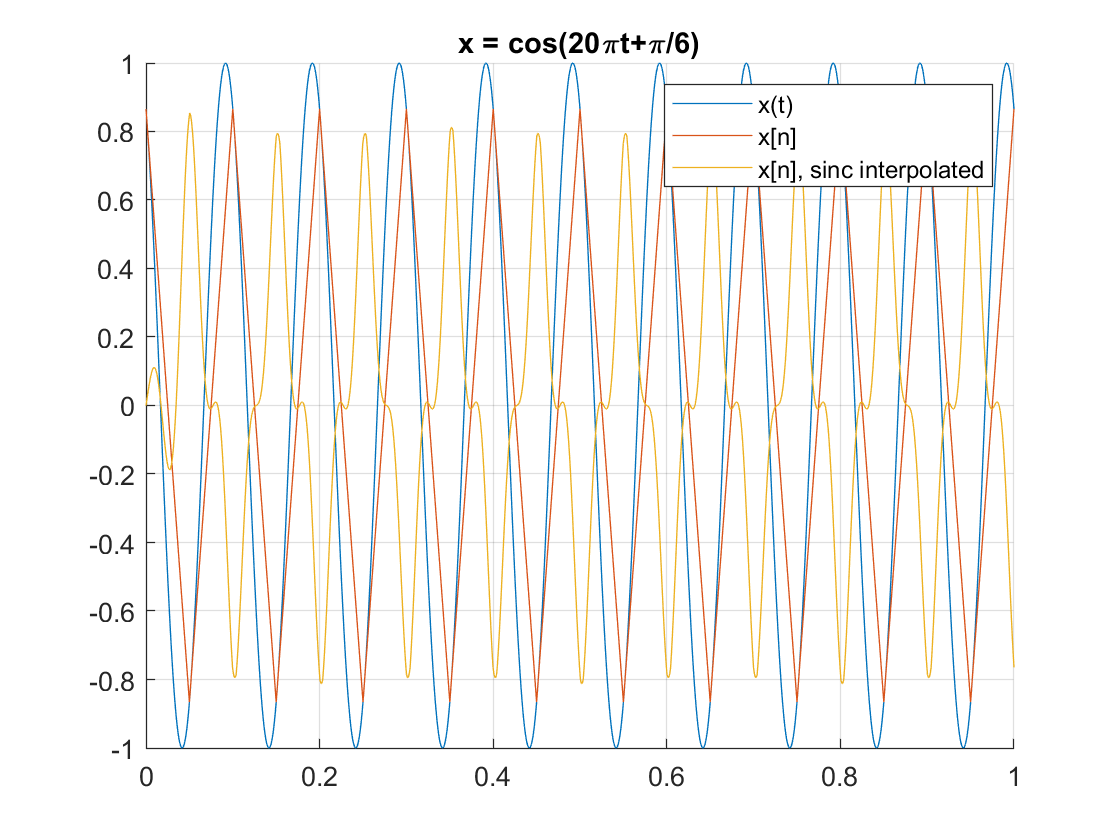

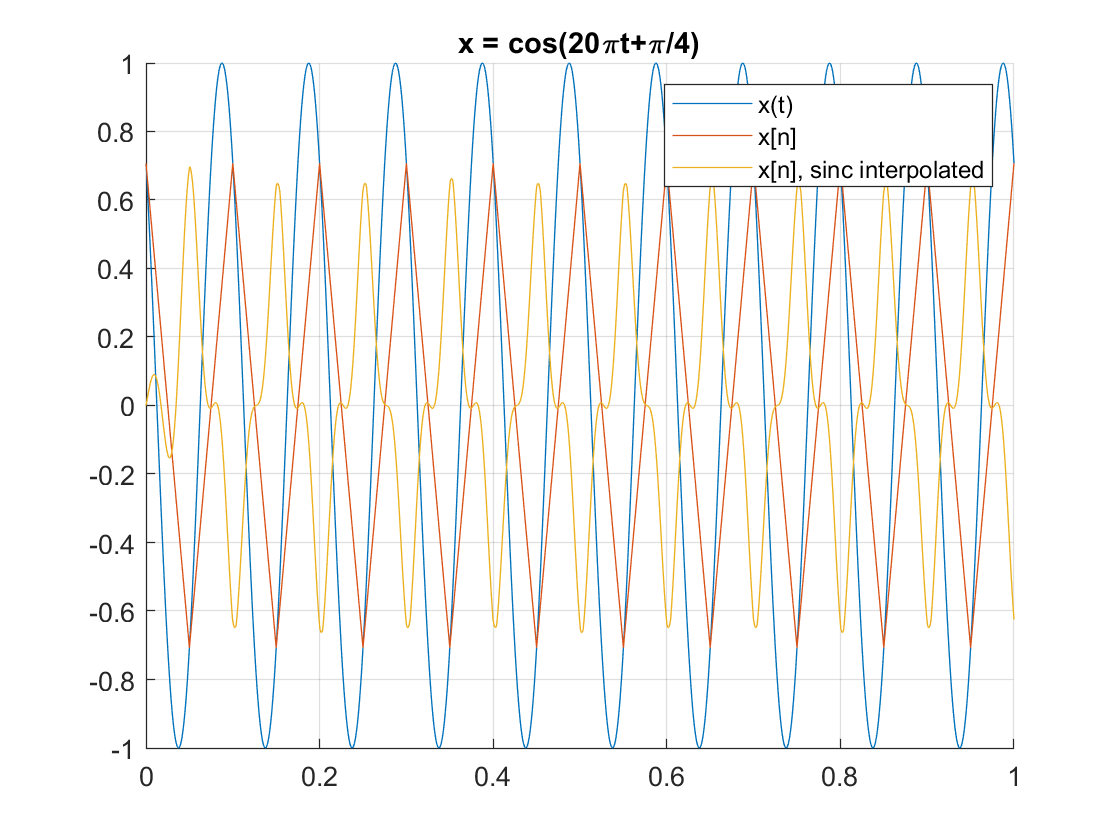

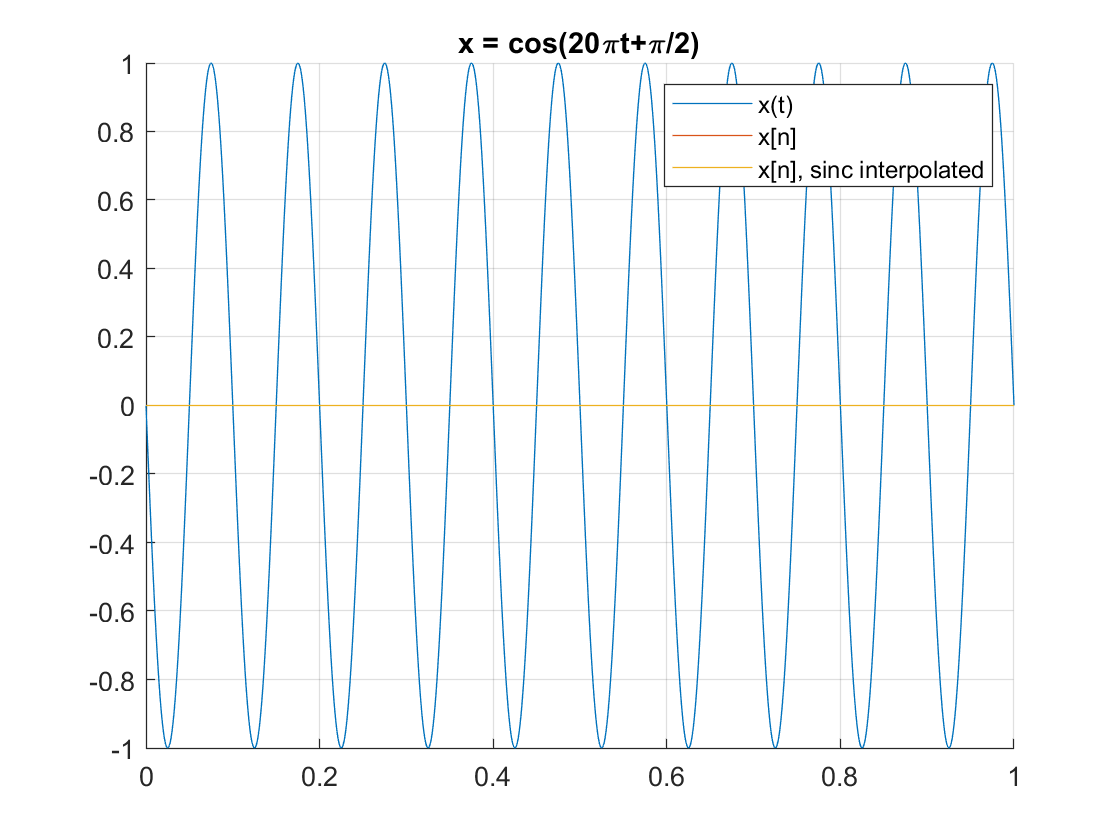

%first set corresponds to xt, second xn
sampleDeltas = [0.001;0.05];
tvals = 0:sampleDeltas(1):1;
nvals = 0:sampleDeltas(2):1;


tOnesMat = ones([1,length(tvals)]);
nOnesMat = ones([1,length(nvals)]);

tFreqArgs = [1;1;1;1]*(20.*pi.*tvals);
nFreqArgs = [1;1;1;1]*(20.*pi.*nvals);

thetas = [0,pi/6,pi/4,pi/2];
strThetas = {'0','\pi/6','\pi/4','\pi/2'};
tPhaseArgs = thetas'*tOnesMat;
nPhaseArgs = thetas'*nOnesMat;

xt = cos(tFreqArgs+tPhaseArgs);
xn = cos(nFreqArgs+nPhaseArgs);


indexRatio = size(tvals,2)./size(nvals,2);

sincKernal = sinc(linspace(-3,+3,100));


for k = 1:size(xn,2)
    xSpread(:, 1+(round((k-1).*indexRatio))  ) = xn(:,k); 
end
spreadIndicies = linspace(0,1,size(xSpread,2));

xRecon = zeros([4,size(spreadIndicies,2)]);
for k = 1:length(thetas)
    temp = conv(sincKernal,xSpread(k,:),'full');
    xRecon(k,1:length(spreadIndicies)) = temp(1,1:length(spreadIndicies));
end




close all;
for k = 1:size(xt,1)
    hold on;
    plot(tvals,xt(k,:)');
    plot(nvals,xn(k,:)');
    plot(spreadIndicies, xRecon(k,:)');
    
    %this was just used for debugging purposes
    %plot(spreadIndicies, xSpread(k,:)');
    title(strcat(strcat('x = cos(20\pit+',strThetas(k)),')'));
    grid on;
    legend('x(t)','x[n]', 'x[n], sinc interpolated');
    figure;
end

Put your explanations here:

The difference in phase affect where in the input wave the samples are taken. For example when there is no phase shift the samples that are taken match up with the peaks of the input wave. However as larger and larger phase shifts are introduced the samples are taken closer and closer to the zero points. This means that while the periodicity is preserved through the "lucky coindicence" of the sampling rate matching the Nyquist frequency the amplitude data is not. Once we get to a $2\pi$ shift however the samples always match up with the zero point and no data is preserved.

Another point to note is that due to our sinc function existing only in positive time, it applies a phase shift to the outputted signal through the following fourier property:


$$x[n-n_0] \rightarrow^{F} {Xe^{-n_0j\omega}}$$


## Aliasing with Images

We explore aliasing with sounds in Python. Here we explore aliasing with images.

Show an excellent image for the study of aliasing.

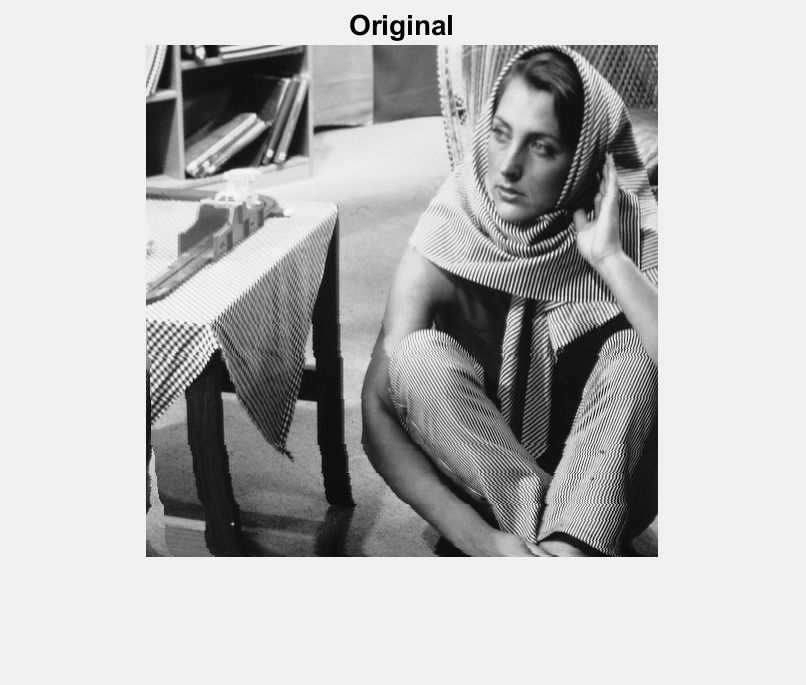

clc
clear all
close all

Im1 = imread('barbara_gray.bmp') ;
figure
set(gcf,'Visible','On')
imshow(Im1)
title('Original')

[height, width, depth] = size(Im1) 

height = 512

width = 512

depth = 1

Downsample the image with no prefiltering

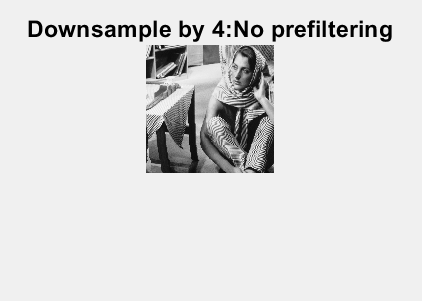

% in case bit depth is three (if trying other images)
Im2 = Im1(:,:,1) ;

% downsample no prefiltering
M = 4 ;
% write code to downsample the image by a factor of M
% put code here
Im3 = Im2(1:M:height, 1:M:width);

% plot downsampled image
figure
set(gcf,'Visible','On')
imshow(Im3)
title(['Downsample by ' num2str(M) ':No prefiltering']) ;

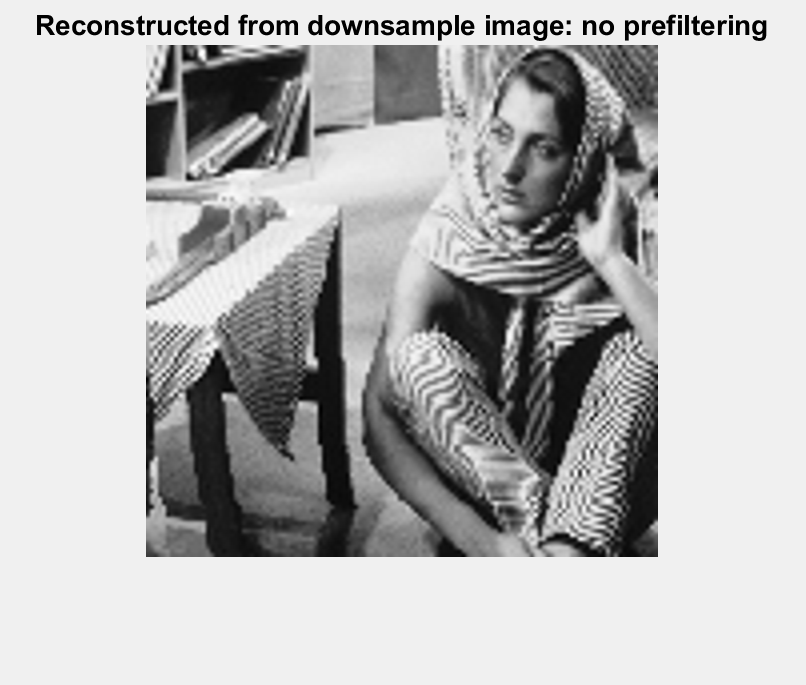


% reconstruct to original size
Im4 = imresize(Im3, [height,width],'bicubic');
figure
set(gcf,'Visible','On')
imshow(Im4)
title(['Reconstructed from downsample image: no prefiltering'])

Downsample with low-pass prefiltering

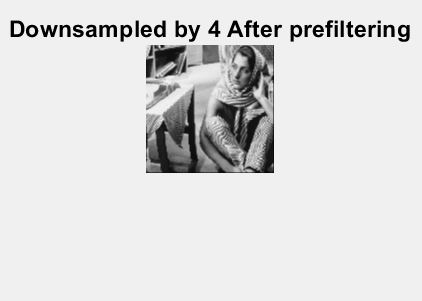

% downsample by a factor of M, after prefiltering
% apply a Gaussian filter to the image
% use the fspecial function to create a Gaussian filter
% explore reasonable values for the filter parameters
% use imfilter to apply the filter to the original image.
% put your code here

Im5 = Im2(1:M:height, 1:M:width);

filtSize = 4;
filtSigma = 0.1;
gaussFilter = fspecial('gaussian',filtSize,filtSigma);
Im6 = imfilter(Im5,gaussFilter);
% plot the downsampled image with prefiltering
figure
set(gcf,'Visible','On')
imshow(Im6)
title(['Downsampled by ' num2str(M) ' After prefiltering']) ;

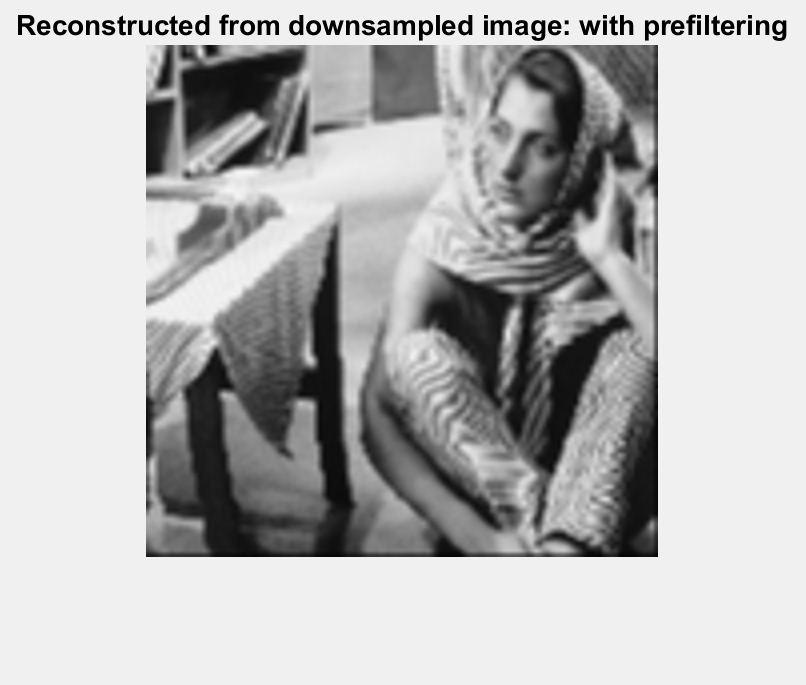


Im7 = imresize(Im6,[height,width],'bicubic') ;
figure
set(gcf,'Visible','On')
imshow(Im7)
title('Reconstructed from downsampled image: with prefiltering')

## Explain your Observations

Explain why aliasing should occur. Explain what you observe with aliasing. Explain why there is an improvement with the application of a prefilter.

The aliasing will occur when we downsample in areas of very high frequency, the obvious example here is the stripes of the scarf and pants. These alternations between white and black can be thought of as peaks and troughs of some periodic function, in fact if we plot the intensities in a 3-d plane and then look side on it becomes obvious.

Below is a small section of the striped pants, plotted both side on and from top down in 3d space, illustrating how an image can have periodic high frequency components.

These peaks are then aliased when the downsampling ocurrs since they are above the Nyquist frequency of our downsampling operation. By applying the gaussian blur (low pass filter) these peaks are smoothed out and blurred together, removing the high frequency components of the image and thereby stopping aliasing from occurring . 

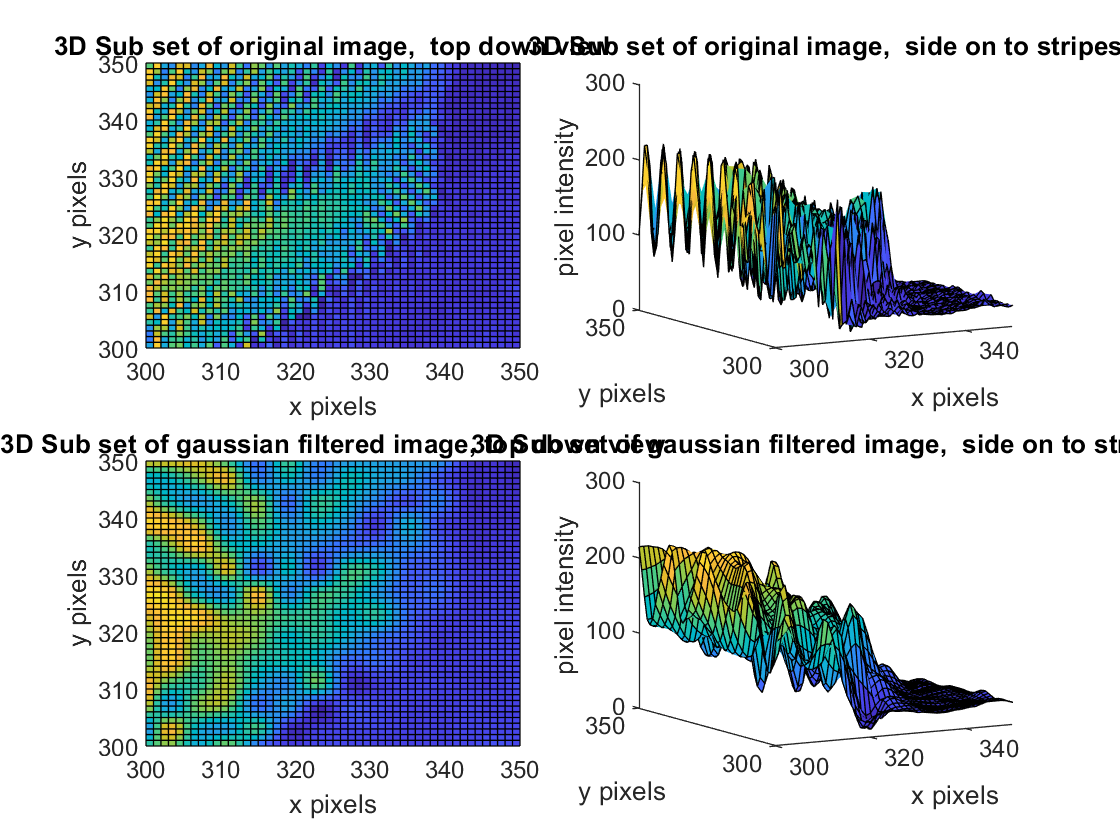

figure;
subplot(2,2,1);
surface(1:width,1:height,Im1);
title('3D Sub set of original image,  top down view');
xlabel('x pixels');
ylabel('y pixels');
zlabel('pixel intensity');
xlim([300,350]);
ylim([300,350]);
view(0,90);

subplot(2,2,2);
title('3D Sub set of original image,  side on to stripes')
surface(1:width,1:height,Im1);
xlabel('x pixels');
ylabel('y pixels');
zlabel('pixel intensity');
xlim([300,350]);
ylim([300,350]);
view([-30 11]);

subplot(2,2,3);
title('3D Sub set of gaussian filtered image, top down view')
surface(1:width,1:height,Im4);
xlabel('x pixels');
ylabel('y pixels');
zlabel('pixel intensity');
xlim([300,350]);
ylim([300,350]);
view(0,90);

subplot(2,2,4);

surface(1:width,1:height,Im4);
title('3D Sub set of gaussian filtered image,  side on to stripes')
xlabel('x pixels');
ylabel('y pixels');
zlabel('pixel intensity');
xlim([300,350]);
ylim([300,350]);
view([-30 11]);